# Chapter 1

% create different types of matrices
z = zeros(5, 5)

z =      0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0


class(z) % type of z

ans = 'double'


z = zeros(5, 5, 'uint16')

z = 5×5 uint16 matrix
   0   0   0   0   0
   0   0   0   0   0
   0   0   0   0   0
   0   0   0   0   0
   0   0   0   0   0


class(z)

ans = 'uint16'


i = eye(5, 5) % identity matrix

i =      1     0     0     0     0
     0     1     0     0     0
     0     0     1     0     0
     0     0     0     1     0
     0     0     0     0     1



one = ones(5, 5, 3)  % 5x5x3 ones matrix

one = one(:,:,1) =

     1     1     1     1     1
     1     1     1     1     1
     1     1     1     1     1
     1     1     1     1     1
     1     1     1     1     1


one(:,:,2) =

     1     1     1     1     1
     1     1     1     1     1
     1     1     1     1     1
     1     1     1     1     1
     1     1     1     1     1


one(:,:,3) =

     1     1     1     1     1
     1     1     1     1     1
     1     1     1     1     1
     1     1     1     1     1
     1     1     1     1     1



[r, c, ch] = size(one)  % shape of matrix

r = 5

c = 5

ch = 3

fprintf("rows = %d, cols = %d, channels = %d\n", r, c, ch) % printing to screen

rows = 5, cols = 5, channels = 3



r = randn(5, 5, 3)  % normally distributed random numbers

r = r(:,:,1) =

   -0.1748    0.1283    1.9437    2.2957   -0.8481
   -0.4807   -1.4424   -1.0847    2.7526   -0.7648
    0.8368    1.3025    0.2268    0.1383   -1.1277
    2.5383    1.4099    1.0989   -1.9071    0.0782
   -1.3233   -1.6625    0.1472   -0.3650    2.1066


r(:,:,2) =

   -0.7158    1.0260   -0.8999    0.9877   -0.7745
   -0.2805    0.8707    0.6347    0.3929    0.7868
    1.1665   -0.3818    0.0675    0.1946    1.4089
    1.2128    0.4289   -0.1871    0.2798   -0.5341
    0.4855   -0.2991    0.2917    0.0512    1.9278


r(:,:,3) =

   -0.1762    0.3539   -2.4995   -1.0059   -1.6338
   -0.2438    1.5970   -0.1676    0.7907    0.7612
   -0.8976    0.5275    0.3530   -0.1166    1.1933
   -0.7923    0.8542    0.7173    0.5531    1.6321
   -0.9530    1.3418   -1.3049   -0.9606   -1.5322



mn = mean(r, "all")  % mean of all elements

mn = 0.1647

mn_cols = mean(r)  % mean of each column

mn_cols = mn_cols(:,:,1) =

    0.2793   -0.0528    0.4664    0.5829   -0.1111


mn_cols(:,:,2) =

    0.3737    0.3289   -0.0186    0.3812    0.5630


mn_cols(:,:,3) =

   -0.6126    0.9349   -0.5803   -0.1479    0.0841



sd = std(r, [], "all")  % std of all values

sd = 1.1049

sd = std(r)  % row vector with std of each column

sd = sd(:,:,1) =

    1.4804    1.4604    1.1344    1.9324    1.3189


sd(:,:,2) =

    0.8603    0.6498    0.5778    0.3612    1.1854


sd(:,:,3) =

    0.3728    0.5278    1.3166    0.8322    1.5531




x = [1, 2, 3, NaN;
    NaN, 5, 5, 5;
    9, 0, NaN, 0]

x =      1     2     3   NaN
   NaN     5     5     5
     9     0   NaN     0


% replace NaN values with -1 using logical indexing
x(isnan(x)) = -1

x =      1     2     3    -1
    -1     5     5     5
     9     0    -1     0


% plot as image
r = randi(11, 11, 3)

r =      3     4     9
     2     3     6
     6     6    10
     3    10     2
    10     7     5
     2     2    11
     1     5    11
     7     1     8
     9     6     7
     4     5     4


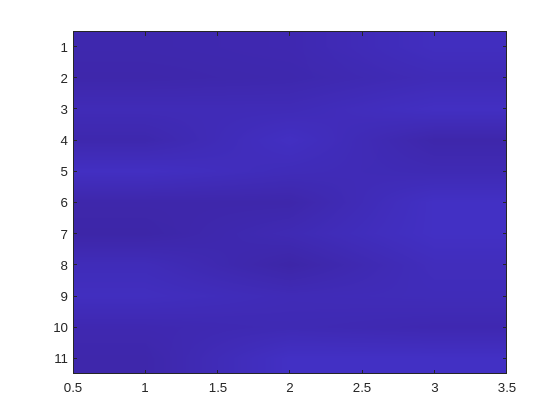

image(r, "Interpolation","bilinear")

r_1_7 = randi(7, [5, 9])

r_1_7 =      1     6     4     3     6     5     5     2     1
     6     6     3     4     6     2     5     6     6
     5     3     5     5     7     2     1     6     1
     6     4     3     7     1     5     3     2     5
     3     7     6     3     3     5     4     6     3


r_11_21 = randi([11, 21], 7)  % 7x7 random integers between 11 and 21

r_11_21 =     19    11    17    15    12    19    11
    16    21    19    12    20    19    13
    16    13    11    13    12    16    18
    20    18    11    13    21    18    18
    14    17    21    14    15    20    20
    15    18    18    12    11    11    17
    21    14    13    14    14    14    11


m = [1:99]

m =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


t = datasample(m, 5, "Replace", false)  % select 5 elements at random without repetetion

t =     92    79    28    53    94


f_handle_sum = @max  % creating a function handle

f_handle_sum = function_handle with value:
    @max


f_handle_sum(5, 7)

ans = 7

m = [1, 2, 3;
    4, 5, 6]

m =      1     2     3
     4     5     6


m .^ 2  % element wise power, same rule for all element wise operations - .<op>

ans =      1     4     9
    16    25    36


m .* [2, 0, 1]  % applies broadcasting

ans =      2     0     3
     8     0     6


fx = @(x1, x2, x3) (x1 ^ 2 + x2 ^ 3 + x3)  % using a function handle to create a function

fx = function_handle with value:
    @(x1,x2,x3)(x1^2+x2^3+x3)


fx(2, 1, 4)

ans = 9

kp_mask = [0, 0, 0, 0; ...
    0, 1, 1, 0; ...
    0, 0, 1, 1]

kp_mask =      0     0     0     0
     0     1     1     0
     0     0     1     1


one_pos = kp_mask ~= 0

one_pos = 3×4 logical array
   0   0   0   0
   0   1   1   0
   0   0   1   1


one_pos(:)

ans = 12×1 logical array
   0
   0
   0
   0
   1
   0
   0
   1
   1
   0


[r, c, v] = find(kp_mask == 1)  % find where == 1, row, col and the value (1 in this case)

r =      2
     2
     3
     3


c =      2
     3
     3
     4


v = 4×1 logical array
   1
   1
   1
   1


[r, c, v] = find(kp_mask)  % find row, col, values , where kp_mask is non-zero

r =      2
     2
     3
     3


c =      2
     3
     3
     4


v =      1
     1
     1
     1


% table arrays
m = [1, 2, 3;
    3, 4, 5;
    7, 8, 9]

m =      1     2     3
     3     4     5
     7     8     9


table(m)  % convert to a column table

ans = 3×1 table
         m     
    ___________

    1    2    3
    3    4    5
    7    8    9


array2table(m)  % adds some automatic headers for each column

ans = 3×3 table
    m1    m2    m3
    __    __    __

    1     2     3 
    3     4     5 
    7     8     9 


tab = array2table(m, "VariableNames", ["height", "width", "length"])  % specify column headers

tab = 3×3 table
    height    width    length
    ______    _____    ______

      1         2        3   
      3         4        5   
      7         8        9   


tab.width = [] % delete a column

tab = 3×2 table
    height    length
    ______    ______

      1         3   
      3         5   
      7         9   


help sum

 sum Sum of elements.
    S = sum(X) is the sum of the elements of the vector X. If X is a matrix,
    S is a row vector with the sum over each column. For N-D arrays, 
    sum(X) operates along the first non-singleton dimension.
 
    S = sum(X,"all") sums all elements of X.
 
    S = sum(X,DIM) sums along the dimension DIM.
 
    S = sum(X,VECDIM) operates on the dimensions specified in the vector 
    VECDIM. For example, sum(X,[1 2]) operates on the elements contained in
    the first and second dimensions of X.
 
    S = sum(...,OUTTYPE) specifies the type in which the 
    sum is performed, and the type of S. Available options are:
 
    "double"    -  S has class double for any input X
    "native"    -  S has the same class as X
    "default"   -  If X is floating point, that is double or single,
                   S has the same class as X. If

help std

 std Standard deviation.
    For vectors, Y = std(X) returns the standard deviation.  For matrices,
    Y is a row vector containing the standard deviation of each column.  For
    N-D arrays, std operates along the first non-singleton dimension of X.
 
    std normalizes Y by N-1 if N>1, where N is the sample size.  This is
    the sqrt of an unbiased estimator of the variance of the population
    from which X is drawn, as long as X consists of independent,
    identically distributed samples. For N=1, Y is normalized by N.
 
    Y = std(X,1) normalizes by N and produces the square root of the second
    moment of the sample about its mean.  std(X,0) is the same as std(X).
 
    Y = std(X,W) computes the standard deviation using the weight vector W.
    W typically contains either counts or inverse variances.  The length of
    W must equal the lengt